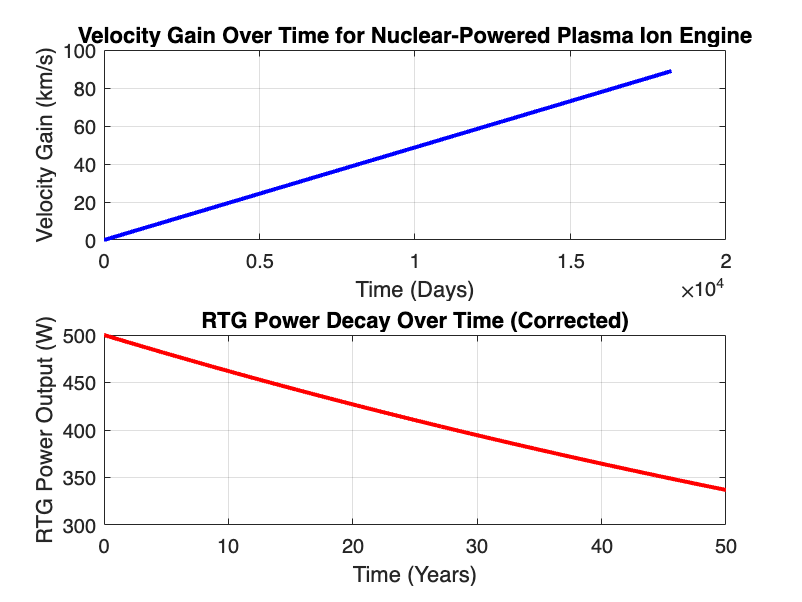

% MATLAB Simulation: Nuclear-Powered Plasma Ion Engine with Long-Term Energy Sustainability

% Constants
mass_xenon = 2.18e-25; % kg (mass of one xenon atom)
charge_xenon = 1.6e-19; % C (elementary charge)
k_B = 1.38e-23; % Boltzmann constant (J/K)
eV_to_J = 1.60218e-19; % Conversion factor from eV to Joules
c = 3e8; % Speed of light (m/s)

% Parameters for Ionization
ionization_energy_xenon = 12.1 * eV_to_J; % Ionization energy in Joules
plasma_temperature = 50000; % K (typical ion thruster plasma temp)
thermal_energy = k_B * plasma_temperature; % Thermal energy of particles

% Nuclear Energy Contribution (Simplified Model)
nuclear_power = 2000; % Watts, power output of a small nuclear reactor
conversion_efficiency = 0.4; % Efficiency of energy conversion
electrical_power_from_nuclear = nuclear_power * conversion_efficiency;

% Solar Panel Contribution (Assuming 10m^2 panel with 30% efficiency)
solar_irradiance = 1361; % W/m^2 (solar constant at Earth's distance)
solar_panel_area = 10; % m^2
solar_efficiency = 0.3; % 30% efficiency
electrical_power_from_solar = solar_irradiance * solar_panel_area * solar_efficiency;

% Corrected RTG Power Contribution using Plutonium-238 Half-life
rtg_initial_power = 500; % Watts, initial power of RTG
half_life_pu238 = 87.7 * 365.25 * 86400; % Half-life in seconds
lambda_pu238 = log(2) / half_life_pu238; % Decay constant

% Total Available Electrical Power Over Time
time_span = linspace(0, 86400 * 365 * 50, 1000); % 50 years in seconds
electrical_power_from_rtg = rtg_initial_power * exp(-lambda_pu238 * time_span);
total_electrical_power = electrical_power_from_nuclear + electrical_power_from_solar + electrical_power_from_rtg;

% Ion Acceleration Process (Electric Field Contribution)
applied_voltage = 3000; % Volts (common for ion thrusters)
ion_velocity = sqrt(2 * applied_voltage * charge_xenon / mass_xenon);

% Magnetic Confinement Efficiency (Estimation)
magnetic_efficiency = 0.85; % 85% efficiency in confinement
effective_thrust_velocity = ion_velocity * magnetic_efficiency;

% Thrust Calculation (Simplified Model)
mass_flow_rate = 1e-6; % kg/s (mass flow rate of xenon ions)
thrust = mass_flow_rate * effective_thrust_velocity;

% Acceleration over Time (For a 1000 kg spacecraft)
spacecraft_mass = 1000; % kg
acceleration = thrust / spacecraft_mass;

% Velocity Gain Over Time
velocity_gain = acceleration * time_span;

% Plot results
figure;
subplot(2,1,1);
plot(time_span / 86400, velocity_gain / 1000, 'b', 'LineWidth', 2); % Convert to days and km/s
xlabel('Time (Days)');
ylabel('Velocity Gain (km/s)');
title('Velocity Gain Over Time for Nuclear-Powered Plasma Ion Engine');
grid on;

subplot(2,1,2);
plot(time_span / (86400*365), electrical_power_from_rtg, 'r', 'LineWidth', 2);
xlabel('Time (Years)');
ylabel('RTG Power Output (W)');
title('RTG Power Decay Over Time');
grid on;